# Homework 4 Math 503B Ashley Jubb

## Question 5) Consider the data in the file ifk.mat. The function d(g), 0<=g<=1 is related to an unknown function m(x), 0<=x<=1 by the mathematical model d(g)= integral 0-->1 xe^-(xg)m(x)dx.

## a) Using the data provided, discretize the integral equation using simple collocation to create a square G matrix and solve the resulting system of equations

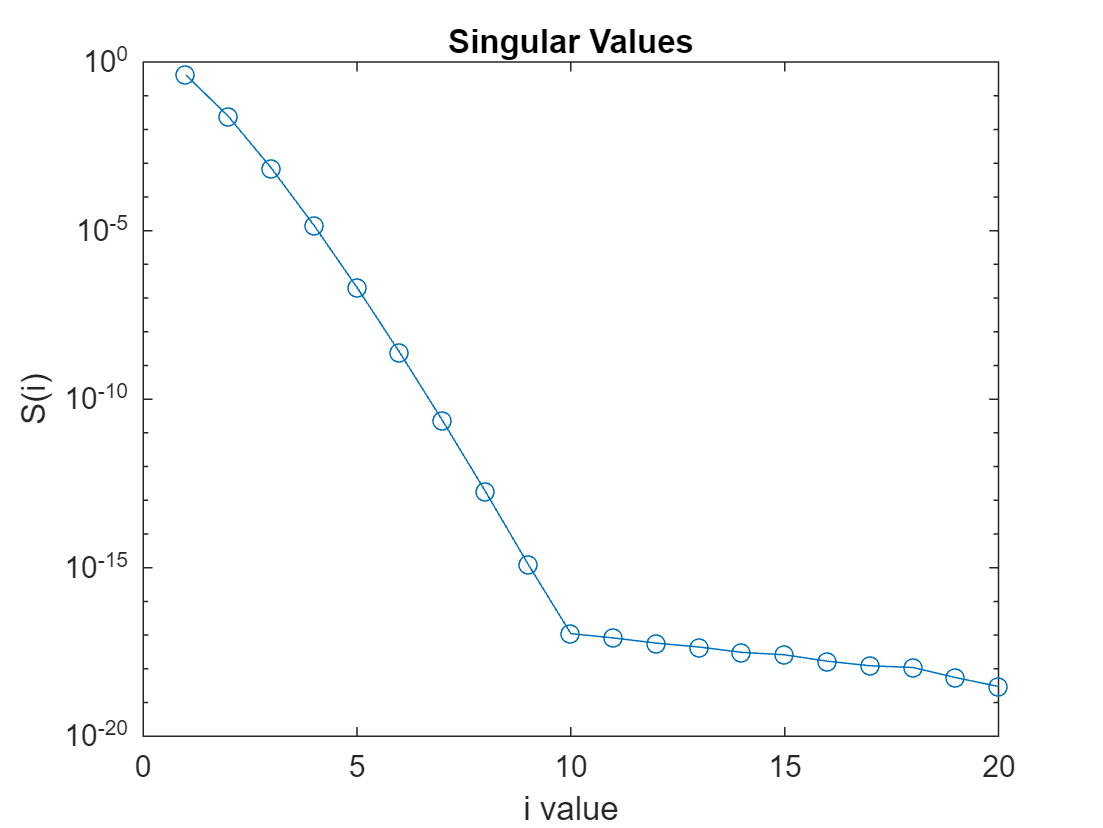

clear;
d=[0.238800000000000; 0.231900000000000; 0.225200000000000; 0.218800000000000;0.212600000000000; 0.206600000000000; 0.200800000000000; 0.195200000000000; 0.189800000000000; 0.184600000000000; 0.179500000000000; 0.174600000000000; 0.169900000000000; 0.165400000000000; 0.161000000000000; 0.156700000000000; 0.152600000000000; 0.148600000000000; 0.144700000000000; 0.141000000000000];
y=linspace(0.0250,0.9750,length(d))';

% Set up G matrix
for i=1 :length(d)
    for j=1:length(d)
        G(i,j)= 0.05*y(j)*exp(-y(j)*y(i)); 
    end
end
% Find SVD
[U,S,V]=svd(G);

% Return column vector containing singular values
s=diag(S);

%plot solution
clf;
figure(1); clf;
plot(s,'-o');set(gca,'yscale','log')
title('Singular Values')
xlabel('i value')
ylabel('S(i)')


% Find rank of G matrix
rank(G)

ans = 9


%Condition number for G matrix
condnum=cond(G)

condnum = 1.4018e+18

## The values of S(i) are zero for i values of 9 or greater.

## b) What is the condition number for this system of equations? Given that the data d(g) are only accurate to about 4 digits, what does this tell you about the accuracy of your solution?

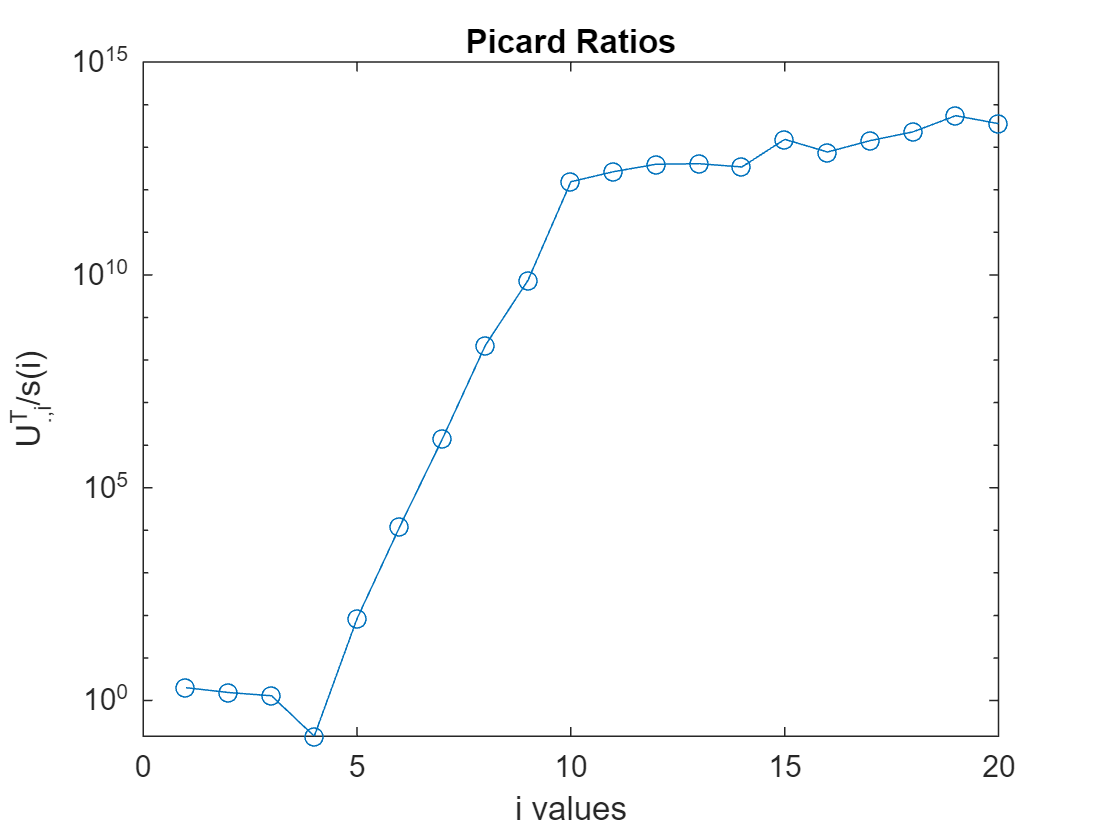

% Find Picard Ratios
for i=1:length(d)
    Up(i)=U(:,i)'*d/s(i);
end

% Plot Picard ratios
figure(2); clf
plot(abs(Up),'-o'); set(gca,'yscale','log')
xlabel ('i values')
ylabel('U^T_{.,i}/s(i)')
title('Picard Ratios')

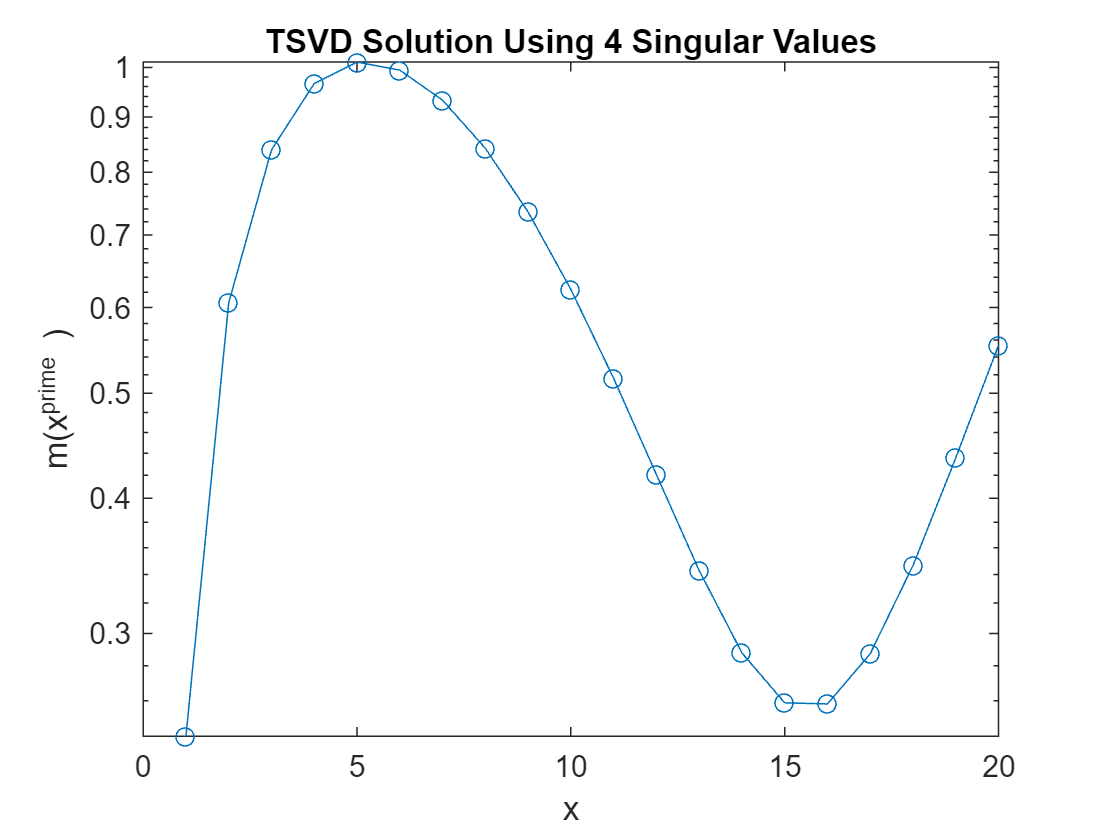

% Picard ratio is zero at i=4

% Use the first 4 singular values in the TSVD soln
n=4;
tsvd=zeros(size(d));
for i=1:n
    tsvd=tsvd+((U(:,i)'*d/s(i))*V(:,i));
end
 
% Plot truncated solution
figure(3); clf;
plot(tsvd,'-o'); set(gca,'yscale','log')
xlabel('x')
ylabel('m(x^prime )')
title('TSVD Solution Using 4 Singular Values')

## Using additional singular values to model the data will produce a grossly inaccurate model

## c) Use the TSVD to compute a solution to this problem. You may find a plot of the Picard ratios |UT.,id/s i| to be especially useful in deciding how many singular values to include.

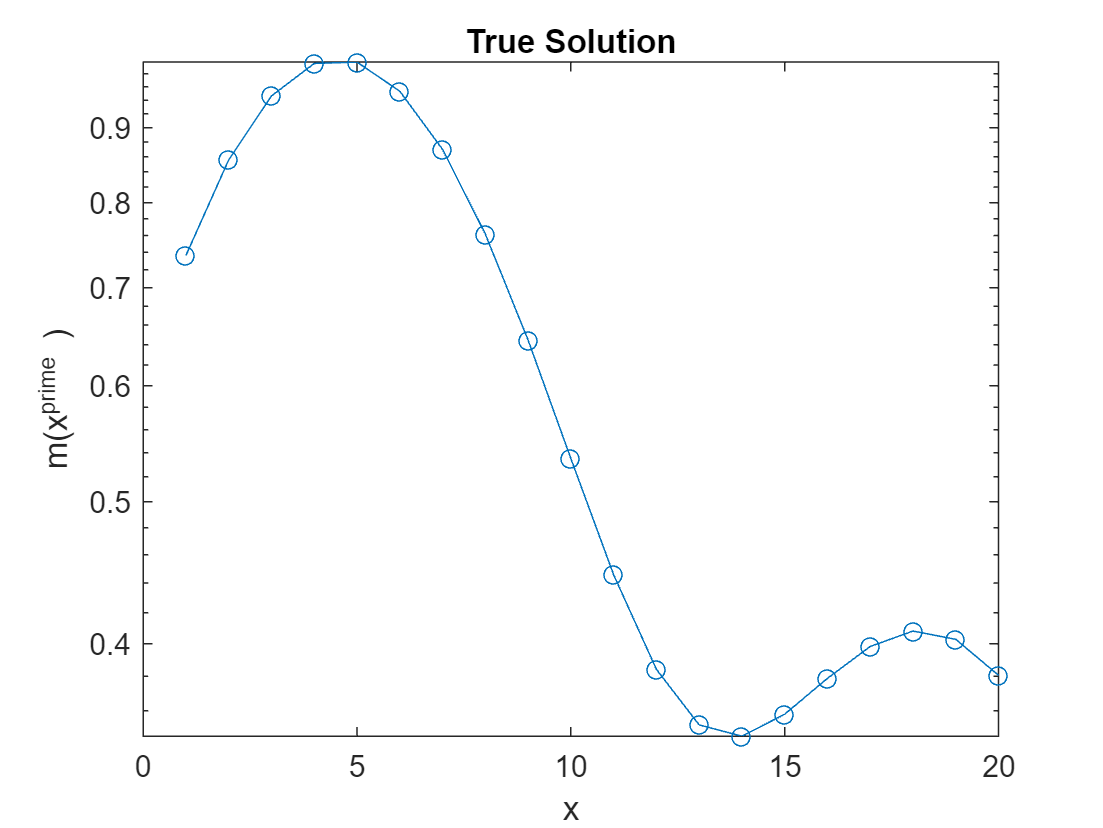


mtrue=exp(-10*(y-0.2).^2)+0.4*exp(-10*(y-0.9).^2);
figure(4);clf
plot(mtrue,'-o'); set(gca,'yscale','log')
xlabel('x')
ylabel('m(x^prime )')
title('True Solution')